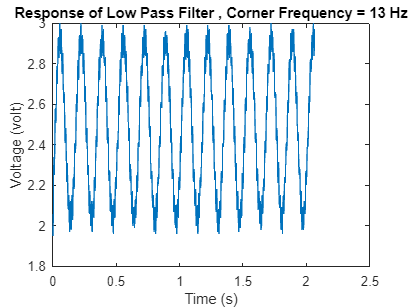

load('Ass2_f13.mat')
x = double(Ass2_f13(2:1000,1)).*1e-4;
y = double(Ass2_f13(2:1000,2));
clear t
syms s t
plot(x,y)
hold on
xlabel('Time (s)')
ylabel('Voltage (volt)')
title('Response of Low Pass Filter , Corner Frequency = 13 Hz');

tt = 0:0.001:2.0663;
desired = 0.5*sin(2*pi*6*t)+0.5*sin(2*pi*84*t)+2.5;
G1 = laplace(desired);
G = 1/(122*1e-4*s+1);
f(t) = simplify(ilaplace(G1*G,t));

Error using indexing
Invalid indexing or function definition. Indexing must follow MATLAB indexing. Function arguments must be symbolic variables, and function body must be sym expression.

Related documentation

plot(tt,f(tt));
y1 = 0.5*sin(2*pi*6*tt);
y2 = 0.5*sin(2*pi*84*tt);
final = y1+y2+2.5;
plot(tt,final,'Color','yellow','LineWidth',0.25)
legend('Aduino Result (Filtered)','Desired Signal (Filtered)','Unfiltered Signal')
hold off

load('Ass2_f48.mat')
x = double(Ass2_f48(2:1000,1)).*1e-4;
y = double(Ass2_f48(2:1000,2));
clear t
syms s t
plot(x,y)
hold on
xlabel('Time (s)')
ylabel('Voltage (volt)')
title('Response of Low Pass Filter , Corner Frequency = 48 Hz');
tt = 0:0.001:2.0663;
desired = 0.5*sin(2*pi*6*t)+0.5*sin(2*pi*84*t)+2.5;
G1 = laplace(desired);
G = 1/(33*1e-4*s+1);
f(t) = simplify(ilaplace(G1*G,t));
plot(tt,f(tt));
y1 = 0.5*sin(2*pi*6*tt);
y2 = 0.5*sin(2*pi*84*tt);
final = y1+y2+2.5;
plot(tt,final,'Color','yellow','LineWidth',0.25)
legend('Aduino Result','Desired Signal','Unfiltered Signal')
hold off